In this demo, we set the flow velocity to be 6, where the pipe system is under flutter. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. Under the addition of external control input at the free end, we are concerned with 

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

%canti
%clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

%clear all;
nmodes = 4;
fcload = 1;
flowspeed =6

flowspeed = 6

miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fext] = build_model1(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

Create dynamical system 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *

   0.0076 + 0.1353i
   0.0076 - 0.1353i
  -0.0704 + 0.4747i
  -0.0704 - 0.4747i
  -0.1225 + 0.0190i
  -0.1225 - 0.0190i
  -0.1240 + 1.0973i
  -0.1240 - 1.0973i



Choose Master subspace (perform resonance analysis)

We take the pair of unstable modes as the master subspace and compute the corresponding 2D unstable SSM

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 9;
resonant_modes = [1,2]; 
S.choose_E(resonant_modes);

sigma_out = -16
sigma_in = -16


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.77E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.14E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.44E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.12E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.69E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.77E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 6.72E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 8.30E-02 MB


%% Reduced dynamics in symbolic form
lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
%y = reduced_dynamics_symbolic(lamdMaster,R0,options)

we indeed see a converged root, which indicates that the system has isola under the addition of forcing. In addition, cubic approximation presents analytical prediction of the critical value of forcing amplitude for the merging of main and isola branches.

phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
for k=1:n
   x    = 1;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   phiend(k) = phin;
end
% disp at the free end
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

### Transient response prediction

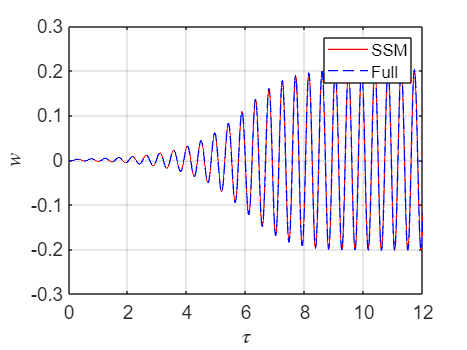

tf     = 12; % <=8 is fine
nsteps = 24000;
stepps=nsteps/tf;
z0     = 0.0*V(:,1); % initial condition (here we select it based on the modal shapes)
z0(1)  = 0.001;
outdof = 1:2*n;
set(DS,'u',[]);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, z0);
[tInt,zInt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);
figure;
plot(traj.time,traj.phy(:,1:n)*phiend,'r-','LineWidth',1); hold on
plot(tInt,zInt(:,1:n)*phiend,'b--','LineWidth',1);
xlabel('$\tau$','Interpreter',"latex",'FontSize',14);
ylabel('$w$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
legend('SSM','Full')
xlim([0,min(traj.time(end),tInt(end))]);

### Stablization via LQR control

auData = construct_autoData(DS, resonant_modes, R0);

tf     = 6;
tspan  = linspace(0,tf,nsteps);
cont   = struct();
cont.Q    = zeros(2*n);
cont.Rhat = 0.1*(phiend'*phiend);
cont.Mhat = 1e4*eye(2*n)*(phiend'*phiend); % 1e4

Bext     = phiend;
% epsilon  = 1e-3;
epsilon  = 1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

**Full dynamics simulation - without control**

om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

SSM Learn

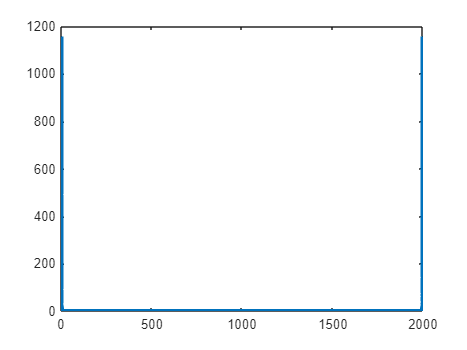

close all

%useddim=[2 5 8 11 14 17 20 24 27 30 33 36 39 42 ];
useddim=[1];
%useddim=[330 990 ]%1650 2310];
%useddim=linspace(1,44,44);
SSMstart=1;

NMTEmin=10000000000000;

xalldimwo=zInt(:,1:n)*phiend;
Yfft=fft(xalldimwo);
plot(stepps/nsteps*(0:nsteps),abs(Yfft),"LineWidth",3)

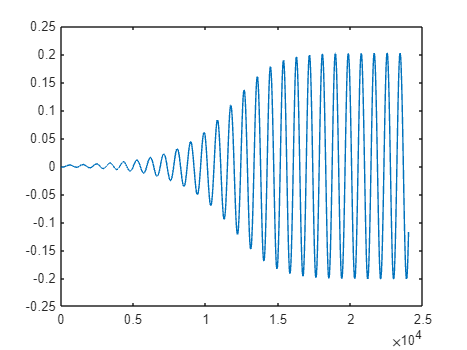

% for i=2:3
%      for j=3:8
%         for k=3:8
            SSMDim=2;
            xfullwoT=xalldimwo(SSMstart:end,useddim)';
            plot(xfullwoT(1,:))

            %xfullwoT=xfullwo(:,1)';
            lengthT=size(xfullwoT,2);
            tspan=linspace(0,lengthT/stepps,lengthT)

tspan =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245



            ydatac=cell(1,2);

            ydatac{1}=tspan;
            %ydatac{2}=xfullwoT(:,1:end-1);
            ydatac{2}=xfullwoT;
            
            overEmbed = 0;
            ydataembed = coordinatesEmbedding(ydatac, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.



            SSMOrder = 5;
            % SSMOrder = 2;
            [IMInfo, SSMChart, SSMFunction] = IMGeometry(ydataembed, SSMDim, SSMOrder);%ydata可以是nxN的矩阵（zauto）

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.053972e-15    6.350e-11    2.998e-14

初始点是满足约束的局部最小值。

优化已完成，因为在初始点处，目标函数沿可行方向在最优性容差值范围内呈现非递减，并且在约束容差值范围内满足约束。

<停止条件详细信息>


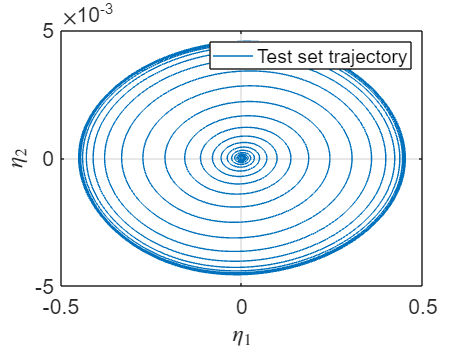



            etaData = projectTrajectories(IMInfo, ydataembed);%Use the chart of a manifold to transform trajectories in the observable space to reduced coordinates on the manifold.


            plotReducedCoordinates(etaData);%fig3 画出测试集和训练集的轨迹?
            legend({'Test set trajectory', 'Training set trajectory'})

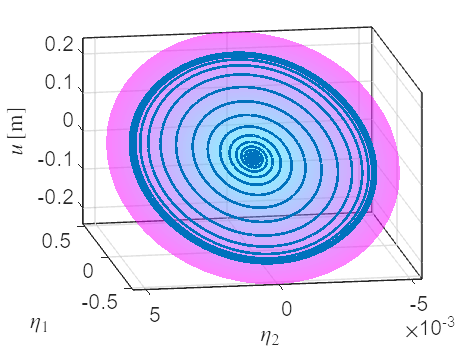



            plotSSMWithTrajectories(IMInfo, 1, ydataembed)%figure4 测试和流形
            view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1         0.504004                          1.96
     1           3         0.138846      0.0768547           1.54  
     2           4        0.0427197              1           2.54  
     3           6       0.00505744       0.418739          0.374  
     4           7      0.000882306              1         0.0331  
     5           8      0.000828461              1         0.0132  
     6           9      0.000814201              1         0.0125  
     7          11      0.000810234       0.407831        0.00764  
     8          12      0.000807783              1        0.00334  
     9          13      0.000806863              1        0.00334  
    10          14      0.000803878              1        0.00459  
    11          15

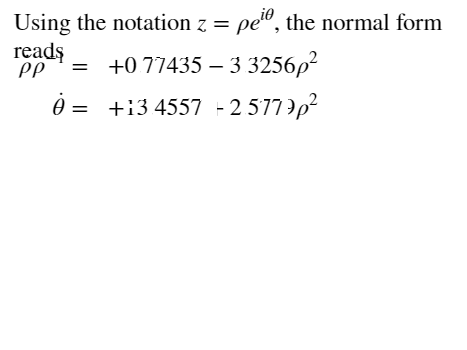



            ROMOrder =3; 
            RDInfo = IMDynamicsFlow(etaData,  'R_PolyOrd', ROMOrder, 'style', 'normalform');

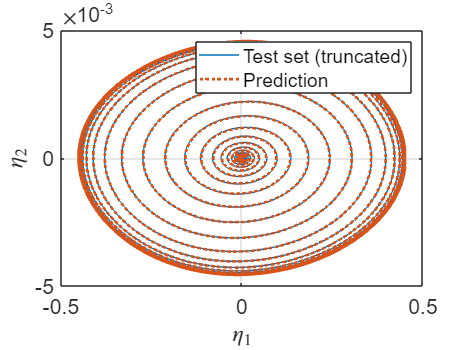

            %
            [yRec, etaRec, zRec] = advect(IMInfo, RDInfo, ydataembed);%通过流形 IMInfo 上 RDInfo 中的来advect yData 中的初始条件。？

            plotReducedCoordinates(etaData, etaRec)%测试和预测
            legend({'Test set (truncated)', 'Prediction'})

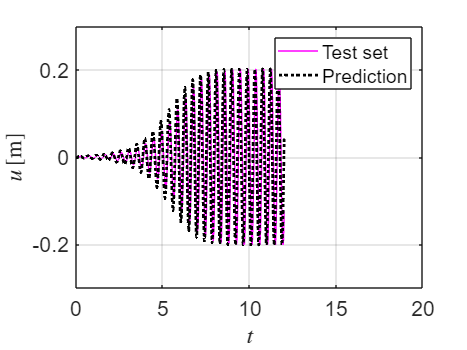

            %
            plotTrajectories(ydataembed, yRec, 'm', 'DisplayName', {'Test set', 'Prediction'})%fig7
            ylabel('$u \, [$m$]$','Interpreter','latex')


            normedTrajDist = computeTrajectoryErrors(yRec, ydataembed);
            NMTE = mean(normedTrajDist) % conjugacy error

NMTE = 0.2763

%             if NMTE<NMTEmin
%                 NMTEmin=NMTE;
%                 iotm=i 
%                 jotm=j 
%                 kotm=k 
%             end
% 
% 
%         end
%     end
% end
%xfullwoT=yRec{2};



% xfullwoTall=xalldimwo(200:end,4)';
% %xfullwoT=xfullwo(:,1)';
% lengthTall=size(xfullwoTall,2);
% tspan=linspace(0,lengthTall*0.00005,lengthTall)
% 
% ydataall=cell(1,2);
% 
% ydataall{1}=tspan;
% %ydatac{2}=xfullwoT(:,1:end-1);
% ydataall{2}=xfullwoTall;
% 
% ydatatestembed = coordinatesEmbedding(ydataall, SSMDim, 'OverEmbedding', overEmbed);
% 
% [yRectest, etaRectest, zRectest] = advect(IMInfo, RDInfo, ydatatestembed);
% 
% etaDatatest = projectTrajectories(IMInfo, ydatatestembed)
% plotReducedCoordinates(etaDatatest, etaRectest)%测试和预测
% legend({'Test set (truncated)', 'Prediction'})
% 
% plotTrajectories(ydatatestembed, yRectest, 'm', 'DisplayName', {'Test set', 'Prediction'})

TRAIN FOR DMD MULSP

close all

ustart=15000;
SSMstart=ustart;

multrainnum=19;
%urand=0.1*randi([-1,1],2,20000);
z0ssmstart=zInt(SSMstart+1,:);
omega0=15;


%urandspall=cell(1,trainnum);


urandtotalsp=[];
xalldimtotalsp=[]; 
xautototalsp=[];
%As=-1;

for A=1:2
    for k=1:multrainnum

        omegatrain=(omega0+(k-1)*10);
        % omegatrain=(omega0^(k-1));
        utlength=ceil(2*pi/omegatrain*stepps);
        while utlength<20
            utlength=utlength+utlength;
        end
        urandallsp=zeros(1,utlength);
        
        %As=-1*As;

        for i=1:1:utlength
            for j=1:1

                urandallsp(j,i)=(2*A)*1e-1*sin(omegatrain/stepps*i);

            end
        end

        urandtotalsp=[urandtotalsp,urandallsp];

        %xautototalsp=[xautototalsp,yRec{2}(:,1:utlength)];

    end
end


totaldatalength=size(urandtotalsp,2)

totaldatalength = 7458

if totaldatalength>nsteps-ustart
    totaldatalength=nsteps-ustart;
    urandtotalsp=urandtotalsp(:,1:totaldatalength)
end
nstepsp=totaldatalength;
tfsp=(totaldatalength)/stepps;
urandtime=linspace(0,tfsp,nstepsp);
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandtotalsp',t));
set(DS,'u',ufun)
[tfullwRcsp, xfullwRcsp,~,xalldimsp] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


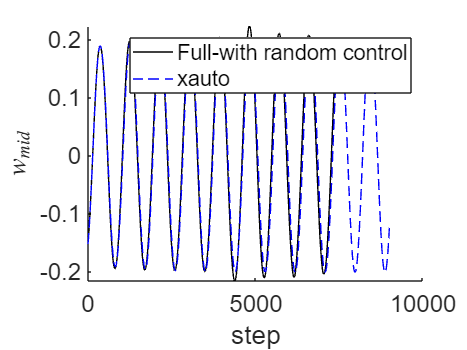



figure;hold on
plot(xalldimsp(:,1:4)*phiend,'k-','DisplayName', 'Full-with random control');
%plot(xalldimwo(1:9000,4)','r--','DisplayName', 'Full-without control')
plot(xalldimwo(SSMstart:end,1)','b--','DisplayName', 'xauto');
legend("show")
xlabel("step")
ylabel("$w_{mid}$",'Interpreter','latex')
set(gca,'FontSize',18)


figure()
timeurandtotalsp=linspace(0,size(urandtotalsp,2)/stepps,size(urandtotalsp,2))

timeurandtotalsp =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


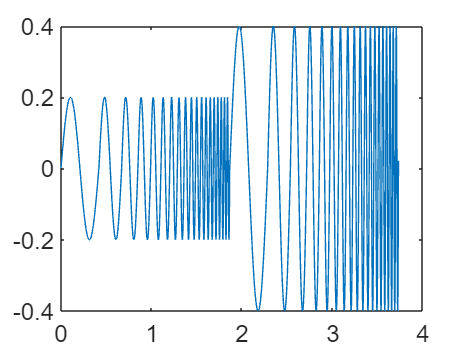

plot(timeurandtotalsp,urandtotalsp,'DisplayName', 'input u')
set(gca,'FontSize',18)

DMD

close all

%tcdim=100;
datalength=totaldatalength;
datastart=1;
%p=tcdim+2;
%r=1;
rembed=5;
windownum=1

windownum = 1

%auto1=yRec{2};
auto1=xfullwoT(:,ustart:end);
auto1=auto1(:,1:datalength);
xrc1=xalldimsp(:,1:4)*phiend;
xrc1=xrc1(1:datalength,:)';
X=(xrc1-auto1)/epsilon;

urand1=urandtotalsp%(1,SSMstart:SSMstart+datalength);

urand1 =     0.0015    0.0030    0.0045    0.0060    0.0075    0.0090    0.0105    0.0120    0.0135    0.0150    0.0165    0.0180    0.0195    0.0210    0.0225    0.0239    0.0254    0.0269    0.0284    0.0299    0.0314    0.0329    0.0343    0.0358    0.0373    0.0388    0.0402    0.0417    0.0432    0.0446    0.0461    0.0475    0.0490    0.0504    0.0519    0.0533    0.0548    0.0562    0.0577    0.0591    0.0605    0.0620    0.0634    0.0648    0.0662    0.0676    0.0690    0.0705    0.0719    0.0733


nstepdmd=datalength;%总数据长度
tfdmd=(datalength)/stepps;
tspandmd=linspace(0,tfdmd,nstepdmd);


%%%%%%%%%%delay embed
NMTEmax=100000;
% for i=1:150
    DMDdim=13;

    Xcell=cell(1,2);
    ucell=cell(1,2);

    Xcell{1}=tspandmd;
    Xcell{2}=X(:,1:end);
    ucell{1}=tspandmd; 
    ucell{2}=urand1;

    overEmbed = 0;
    Xembed = coordinatesEmbedding(Xcell, DMDdim, 'OverEmbedding', overEmbed);

The 27 embedding coordinates consist of the measured state and its 26 time-delayed measurements.


    uembed = coordinatesEmbedding(ucell, 1, 'OverEmbedding', overEmbed);

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


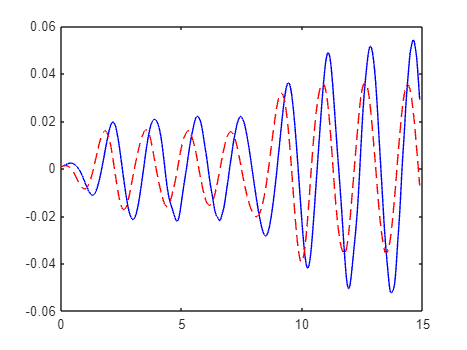

    datalengthemb=size(Xembed{2},2)-1;
    rembed=size(Xembed{2},1);


    %[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength-1,datastart,r,windownum,X,urand1);
    %[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,rembed,windownum,Xembed{2},uembed{2});
    %[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength,datastart,rembed,windownum,X,urand1);
    [Admv,Bdmv,Uupmv,datastartmv,datalengthmv,DMDtraj]=DMD1(datalengthemb,datastart,5,windownum,Xembed{2},urand1,0);


    Xnmt=cell(1,2);
    Xnmt{1}=Xembed{1}(1,1:size(DMDtraj{1},2));
    Xnmt{2}=Xembed{2}(1,1:size(DMDtraj{1},2));
    normedTrajDist = computeTrajectoryErrors(DMDtraj, Xnmt);
    NMTE2 = mean(normedTrajDist); % conjugacy error
%     if NMTE2<NMTEmax
%         iotm=i;
%         NMTEmax=NMTE2;
%     end
% end

## DMD test


trainnum=1;
%urand=0.1*randi([-1,1],2,20000);

utlength=10000;
splength=utlength/trainnum;

nstepsp=utlength;%总数据长度
tfsp=(utlength)/stepps;
urandtime=linspace(0,tfsp,nstepsp)

urandtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


urandalltestsp=zeros(1,nstepsp);



for k=1:trainnum
    for i=1:1:splength
        for j=1
            urandalltestsp(j,i)=6e-3*sin(50/stepps*i);
        end
    end
     %urandallsp=[urandallsp,urandsp];
end

%set(DS,'D',Bext1)
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandalltestsp',t));
%set(DS,'u',ufun);
set(DS,'u',ufun);


[tfulltestsp, xfulltestsp,~,xalldimtestsp] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0);

datalength=10000;%%%%%
tstest=linspace(0,datalength/stepps,datalength)

tstest =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245



XRC=xalldimtestsp(1:datalength,useddim)';
u=urandalltestsp;
Xtest=XRC-xfullwoT(:,1:datalength)

Xtest =     0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030


% u=urand;
% XRC=xfulltestwRc';
Xtestcell=cell(1,2);
utestcell=cell(1,2);


Xtestcell{1}=tstest(1:end-1);
Xtestcell{2}=Xtest(:,1:size(Xtestcell{1},2));
utestcell{1}=tstest(1:end-1);
utestcell{2}= urandalltestsp(:,1:size(Xtestcell{1},2));

overEmbed = 0;
Xtestembed = coordinatesEmbedding(Xtestcell, DMDdim, 'OverEmbedding', overEmbed);

The 27 embedding coordinates consist of the measured state and its 26 time-delayed measurements.


utestembed = coordinatesEmbedding(utestcell, DMDdim, 'OverEmbedding', overEmbed);

The 27 embedding coordinates consist of the measured state and its 26 time-delayed measurements.


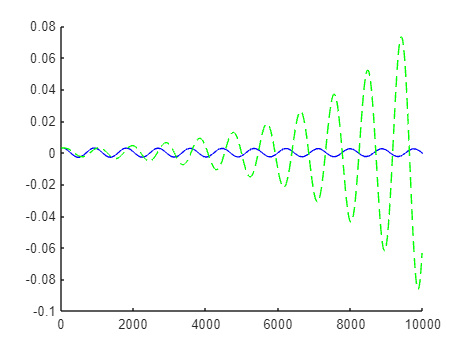

datalengthemb=size(Xtestembed{2},2)-1;

N=datalength;

xt=zeros(size(Admv{1},2),N);
ut=zeros(size(Bdmv{1},2),N);
xt(:,1)=Xtestembed{2}(:,1)/epsilon;
%u=urandall{testnum};

%X2=XRC-auto1;

for k =1:datalength-1
        ut(:,k)=u(:,k);

        xt(:,k+1)=epsilon*(Admv{1}*xt(:,k)+Bdmv{1}*ut(:,k));

end

figure()
hold on
plot(xt(4,:),'b','DisplayName', 'test DMD')
plot(Xtestembed{2}(4,:),'g--','DisplayName', 'test origin')

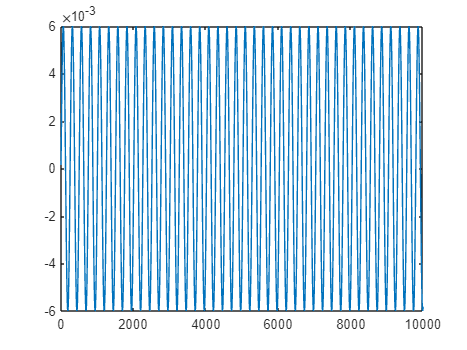


figure()
plot( urandalltestsp)

LQR1

close all

LQRlength=2500;

tspan1=linspace(datastart,datastart+LQRlength,LQRlength);
autodata=xalldimwo(SSMstart+1:SSMstart+LQRlength,useddim)';
epsil=DS.epsilon;


%z00=autodata(:,1);
autocell=cell(1,2);

tspanLQR=linspace(0,LQRlength/stepps,LQRlength)

tspanLQR =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell{1}=tspanLQR(:,1:LQRlength);
autocell{2}=autodata(:,1:LQRlength);

autoembed = coordinatesEmbedding(autocell, DMDdim, 'OverEmbedding', overEmbed);

The 27 embedding coordinates consist of the measured state and its 26 time-delayed measurements.



% Ecell=cell(1,2)
% Ecell{1}=tspanLQR(:,1:LQRlength);
% xalldimwET=xalldimwE';
% Ecell{2}=xalldimwET(useddim,SSMstart+1:SSMstart+LQRlength);
% Eembed = coordinatesEmbedding(Ecell, DMDdim, 'OverEmbedding', overEmbed);

targetdata=autoembed{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed{2},targetdata,windownum,epsil,DS,1,45)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3001    0.3101    0.3201    0.3301    0.3401    0.3501    0.3601    0.3701    0.3802    0.3902    0.4002    0.4102    0.4202    0.4302    0.4402    0.4502    0.4602    0.4702    0.4802    0.4902


prenewtraj = 包含以下字段的 struct :
     time: [1 2.0004 3.0008 4.0012 5.0016 6.0020 7.0024 8.0028 9.0032 10.0036 11.0040 12.0044 13.0048 14.0052 15.0056 16.0060 17.0064 18.0068 19.0072 20.0076 21.0080 22.0084 23.0088 24.0092 25.0096 26.0100 27.0104 28.0108 29.0112 30.0116 31.0120 … ]
       us: [2.7975 2.8155 2.8333 2.8508 2.8682 2.8852 2.9020 2.9186 2.9349 2.9510 2.9668 2.9824 2.9977 3.0128 3.0277 3.0423 3.0567 3.0708 3.0847 3.0983 3.1117 3.1248 3.1377 3.1504 3.1628 3.1750 3.1869 3.1986 3.2101 3.2213 3.2323 3.2430 3.2535 3.2638 … ]
       xt: [27×2474 double]
    xauto: [27×2474 double]


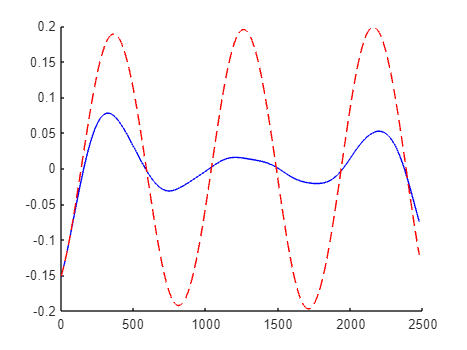



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
plot(prenewtraj.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(autoembed{2}(2,:),'--r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj.us,2)/stepps,size(prenewtraj.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


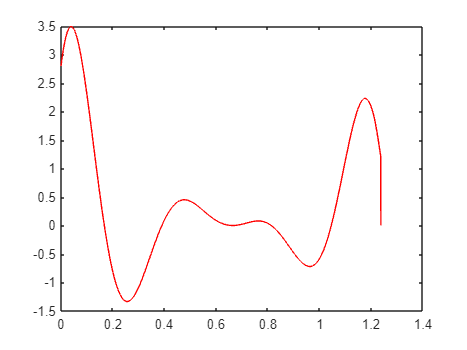

plot(figx,prenewtraj.us(1,:),'r','DisplayName', 'lqr us')

%xlim([0,0.1])

realsystem1

utnew=[prenewtraj.us(1,:)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew,2)/stepps,size(utnew,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew,2)

prestep = 2474

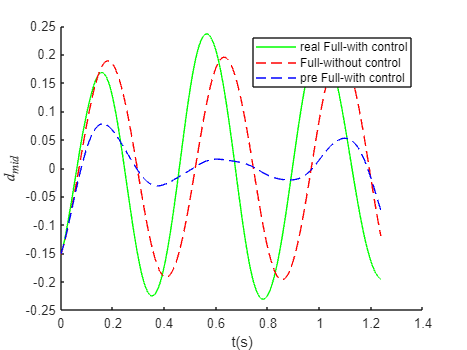

tpref=size(utnew,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-1;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength),'r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.02])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

%set(gca,'FontSize',18)


DMD2

urandtotalsp2=[utnew,urandtotalsp];

totaldatalength2=size(urandtotalsp2,2)

totaldatalength2 = 9932


if totaldatalength2>nsteps-ustart
    totaldatalength2=nsteps-ustart;
    urandtotalsp2=urandtotalsp2(:,1:totaldatalength2)
end

urandtotalsp2 =     2.7975    2.8155    2.8333    2.8508    2.8682    2.8852    2.9020    2.9186    2.9349    2.9510    2.9668    2.9824    2.9977    3.0128    3.0277    3.0423    3.0567    3.0708    3.0847    3.0983    3.1117    3.1248    3.1377    3.1504    3.1628    3.1750    3.1869    3.1986    3.2101    3.2213    3.2323    3.2430    3.2535    3.2638    3.2738    3.2836    3.2931    3.3024    3.3115    3.3204    3.3290    3.3373    3.3455    3.3534    3.3611    3.3685    3.3757    3.3827    3.3894    3.3960


nstepsp=totaldatalength2;
tfsp=(totaldatalength2)/stepps;
urandtime=linspace(0,tfsp,nstepsp);
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandtotalsp2',t));
set(DS,'u',ufun)
[tfullwRcsp2, xfullwRcsp2,~,xalldimsp2] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


%tcdim=100;
datalength2=totaldatalength2;
datastart=1;
%p=tcdim+2;
%r=1;
rembed=5;
windownum=1

windownum = 1

%auto1=yRec{2};
auto1=xfullwoT(:,ustart:end);
auto1=auto1(:,1:datalength2);
xrc1=xfullwRcsp2(:,1:4)*phiend;
xrc1=xrc1(1:datalength2,:)';
X=(xrc1-auto1)/epsilon;

urand1=urandtotalsp2%(1,SSMstart:SSMstart+datalength);

urand1 =     2.7975    2.8155    2.8333    2.8508    2.8682    2.8852    2.9020    2.9186    2.9349    2.9510    2.9668    2.9824    2.9977    3.0128    3.0277    3.0423    3.0567    3.0708    3.0847    3.0983    3.1117    3.1248    3.1377    3.1504    3.1628    3.1750    3.1869    3.1986    3.2101    3.2213    3.2323    3.2430    3.2535    3.2638    3.2738    3.2836    3.2931    3.3024    3.3115    3.3204    3.3290    3.3373    3.3455    3.3534    3.3611    3.3685    3.3757    3.3827    3.3894    3.3960


nstepdmd=datalength2;%总数据长度
tfdmd=(datalength2)/stepps;
tspandmd=linspace(0,tfdmd,nstepdmd);


%%%%%%%%%%delay embed

DMDdim=100

DMDdim = 100


Xcell=cell(1,2);
ucell=cell(1,2);

Xcell{1}=tspandmd;
Xcell{2}=X(:,1:end);
ucell{1}=tspandmd;
ucell{2}=urand1;

overEmbed = 0;
Xembed = coordinatesEmbedding(Xcell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.


uembed = coordinatesEmbedding(ucell, 1, 'OverEmbedding', overEmbed);

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


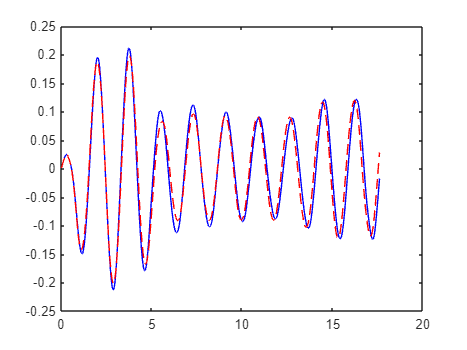

datalengthemb=size(Xembed{2},2)-1;
rembed=size(Xembed{2},1);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength-1,datastart,r,windownum,X,urand1);
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,rembed,windownum,Xembed{2},uembed{2});
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength,datastart,rembed,windownum,X,urand1);
[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,30,windownum,Xembed{2},urand1,0);

feedback test 1

feedbackpoint1=400;
utnewhalf=[prenewtraj.us(1,1:feedbackpoint1),zeros(1,LQRlength-feedbackpoint1)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnewhalf,2)/stepps,size(utnewhalf,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnewhalf,2)

prestep = 2500

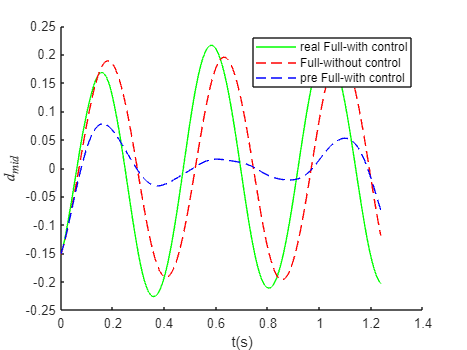

tpref=size(utnewhalf,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnewhalf',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,alldimfbpoint1,xalldimreal] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(prenewtraj.xt,2)-1;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength)','r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

%set(gca,'FontSize',18)

xbehindtemp=xalldimreal(1:figlength,1:4)*phiend;
xbehind=xbehindtemp(feedbackpoint1:end,useddim)';
%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell=cell(1,2)

xbehindcell = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbehindcell{1}=tspanLQR(:,1:size(xbehind,2));
%xbehindcell{2}=xbehind;
xbehindcell{2}=xbehind;
xbehindembed = coordinatesEmbedding(xbehindcell, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


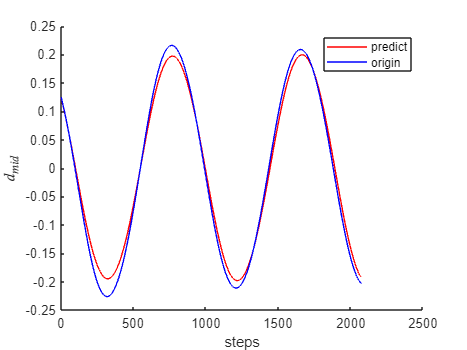

 [xbhRec, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed);
 figure();
 hold on;
 plot(xbhRec{2}(2,:),'r','DisplayName', 'predict');
 plot(xbehind(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')

LQR2

LQRlength2=size(xbhRec{2},2);

tspan2=linspace(datastart,datastart+LQRlength2-1,LQRlength2);
%autodata2=xbehind;
autodata2=xbhRec{2}(1,:);

autocell2=cell(1,2);

tspanLQR2=linspace(0,LQRlength2/stepps,LQRlength2)

tspanLQR2 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell2{1}=tspanLQR2(:,1:LQRlength2);
autocell2{2}=autodata2(:,1:LQRlength2);

autoembed2 = coordinatesEmbedding(autocell2, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



xbhcell=cell(1,2)

xbhcell = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbhcell{1}=tspanLQR2(:,1:LQRlength2);
xbhcell{2}=xbehind(:,1:LQRlength2);
xbhembeded = coordinatesEmbedding(xbhcell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



%targetdata2=autoembed2{2};
targetdata2=xbhembeded{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed2{2},2);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,5,windownum,Xembed{2},urand1,0);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj2 = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed2{2},targetdata2,windownum,epsil,DS,1,80)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2902    0.3002    0.3102    0.3202    0.3302    0.3402    0.3502    0.3602    0.3702    0.3802    0.3902    0.4002    0.4102    0.4202    0.4302    0.4402    0.4502    0.4602    0.4703    0.4803    0.4903


prenewtraj2 = 包含以下字段的 struct :
     time: [1 2.0004 3.0008 4.0012 5.0016 6.0020 7.0024 8.0028 9.0032 10.0036 11.0040 12.0044 13.0048 14.0052 15.0056 16.0060 17.0064 18.0068 19.0072 20.0076 21.0080 22.0084 23.0088 24.0092 25.0096 26.0100 27.0104 28.0108 29.0112 30.0116 31.0120 … ]
       us: [-22.5829 -22.2412 -21.9010 -21.5624 -21.2254 -20.8901 -20.5565 -20.2246 -19.8945 -19.5662 -19.2397 -18.9150 -18.5923 -18.2715 -17.9527 -17.6358 -17.3210 -17.0082 -16.6975 -16.3888 -16.0823 -15.7780 -15.4758 -15.1758 -14.8780 -14.5825 … ]
       xt: [201×1870 double]
    xauto: [201×1870 double]


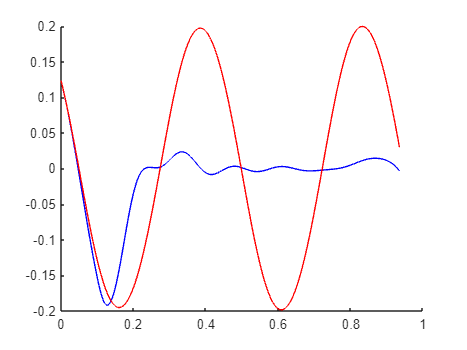



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj2.xt,2)/stepps,size(prenewtraj2.xt,2));
plot(figx,prenewtraj2.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed2{2}(2,:),'r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj2.us,2)/stepps,size(prenewtraj2.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


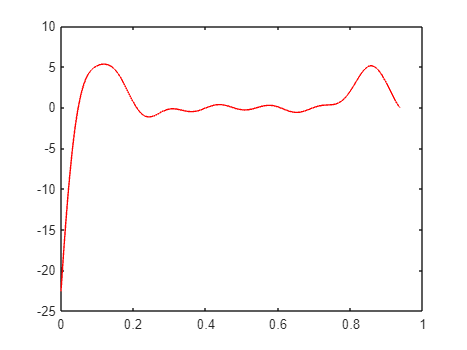

plot(figx,prenewtraj2.us(1,:),'r','DisplayName', 'lqr us')

feedback real system1

utnew2=[prenewtraj.us(:,1:feedbackpoint1),prenewtraj2.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew2,2)/stepps,size(utnew2,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew2,2);
tpref=size(utnew2,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

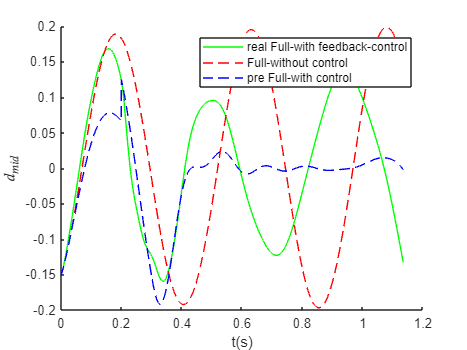


figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength),'r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

feedback test 2

feedbackpoint2=1000;
utnewhalf2=[utnew2(1,1:feedbackpoint2),zeros(1,LQRlength-feedbackpoint2)];
%utnew=[zeros(1,3000),100*ones(1,10000)]

tpref2=size(utnewhalf2,2)/stepps;
closedtime2=linspace(0,tpref2,size(utnewhalf2,2))

closedtime2 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep2=size(utnewhalf2,2)

prestep2 = 2500

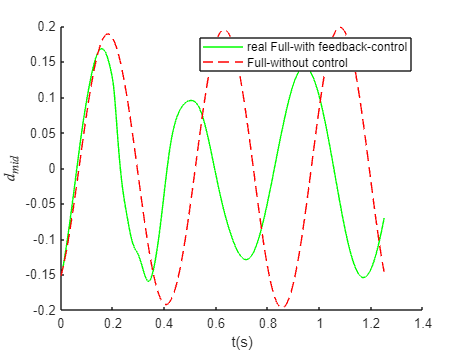


om = 2*pi/tpref2;
ufun = @(t) transpose(interp1(closedtime2,utnewhalf2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre2, xfullpre2,~,xalldimreal2] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep2,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimreal2,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal2(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
%plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

xbehind2=xalldimreal2(feedbackpoint2+1:end-1,1:4)*phiend;
xbehind2=xbehind2'

xbehind2 =     0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0950    0.0949    0.0949    0.0949    0.0948    0.0948    0.0948    0.0947    0.0947    0.0946    0.0945    0.0945    0.0944    0.0943    0.0942    0.0942    0.0941    0.0940    0.0939    0.0938    0.0937    0.0935    0.0934    0.0933    0.0931    0.0930    0.0929    0.0927    0.0925    0.0924    0.0922    0.0920    0.0918    0.0916    0.0914    0.0912    0.0910    0.0908


%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell2=cell(1,2)

xbehindcell2 = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbehindcell2{1}=tspanLQR(:,1:size(xbehind2,2));
xbehindcell2{2}=xbehind2;
xbehindembed2 = coordinatesEmbedding(xbehindcell2, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


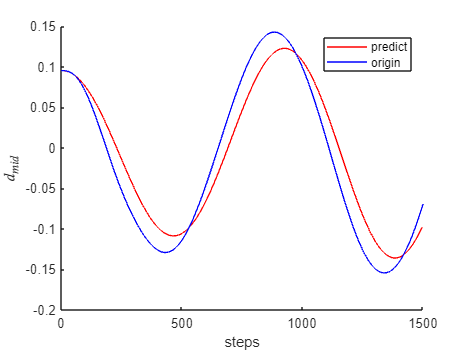


 [xbhRec2, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed2);
 figure();
 hold on;
 plot(xbhRec2{2}(1,:),'r','DisplayName', 'predict');
 plot(xbehind2(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')

LQR3

LQRlength3=LQRlength-feedbackpoint2-2*DMDdim;

tspan3=linspace(datastart,datastart+LQRlength3-1,LQRlength3);
%autodata2=xbehind;
autodata3=xbhRec2{2}(1,:);

autocell3=cell(1,2);

tspanLQR3=linspace(0,LQRlength3/stepps,LQRlength3)

tspanLQR3 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell3{1}=tspanLQR3(:,1:LQRlength3);
autocell3{2}=autodata3(:,1:LQRlength3);
autoembed3 = coordinatesEmbedding(autocell3, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



xbhcell2=cell(1,2)

xbhcell2 = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbhcell2{1}=tspanLQR2(:,1:LQRlength3);
xbhcell2{2}=xbehind2(:,1:LQRlength3);
xbhembeded2 = coordinatesEmbedding(xbhcell2, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.




%targetdata2=autoembed2{2};
targetdata3=xbhembeded2{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed3{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj3 = LQRwdz3(tspan3,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed3{2},targetdata3,windownum,epsil,DS,1,40)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2502    0.2602    0.2702    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3503    0.3603    0.3703    0.3803    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4504    0.4604    0.4704    0.4804    0.4904


prenewtraj3 = 包含以下字段的 struct :
     time: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 … ]
       us: [-7.7146 -7.6584 -7.6020 -7.5454 -7.4887 -7.4319 -7.3749 -7.3179 -7.2607 -7.2034 -7.1460 -7.0886 -7.0311 -6.9735 -6.9159 -6.8582 -6.8005 -6.7427 -6.6850 -6.6272 -6.5694 -6.5117 -6.4539 -6.3962 -6.3385 -6.2808 -6.2232 -6.1656 -6.1081 … ]
       xt: [201×1100 double]
    xauto: [201×1100 double]


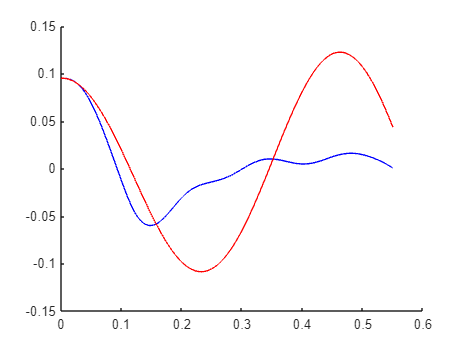



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj3.xt,2)/stepps,size(prenewtraj3.xt,2));
plot(figx,prenewtraj3.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed3{2}(2,:),'r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj3.us,2)/stepps,size(prenewtraj3.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


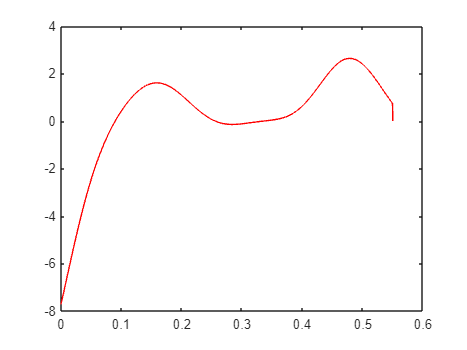

plot(figx,prenewtraj3.us(1,:),'r','DisplayName', 'lqr us')

feedback real system2

utnew3=[utnew2(1,1:feedbackpoint2),prenewtraj3.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew3,2)/stepps,size(utnew3,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew3,2);
tpref=size(utnew3,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew3',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,~,xalldimpre3] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode45','outdof',outdof,'init',z0ssmstart);

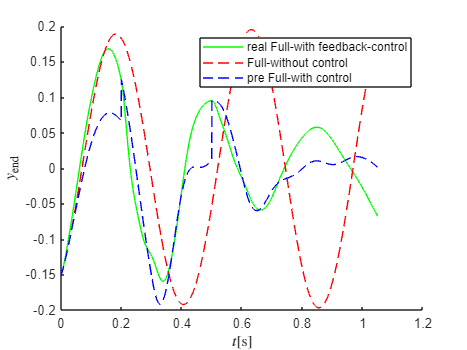

%load canti_fs6_bestfor5.mat
figure;
hold on
feedbacktraj2=[prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:feedbackpoint2-feedbackpoint1),prenewtraj3.xt(1,1:end)];
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimpre3,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimpre3(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, feedbacktraj2(1:size(figx,2)),'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("$t$[s]",'Interpreter','latex')
ylabel("$y_{\rm{end}}$",'Interpreter','latex')

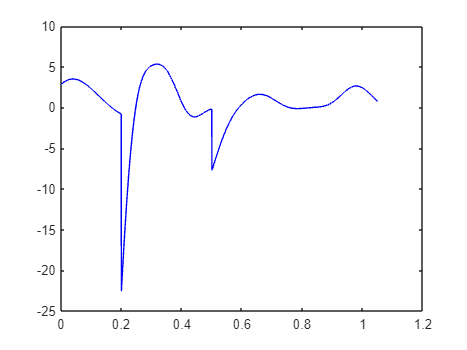

figure()
plot(figx, utnew3(:,1:end-1),'b','DisplayName', 'ut');


close all

LQRlength=2500;

tspan1=linspace(datastart,datastart+LQRlength,LQRlength);
autodata=xalldimwo(SSMstart+1:SSMstart+LQRlength,useddim)';
epsil=DS.epsilon;


%z00=autodata(:,1);
autocell=cell(1,2);

tspanLQR=linspace(0,LQRlength/stepps,LQRlength)

tspanLQR =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell{1}=tspanLQR(:,1:LQRlength);
autocell{2}=autodata(:,1:LQRlength);

autoembed = coordinatesEmbedding(autocell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



% Ecell=cell(1,2)
% Ecell{1}=tspanLQR(:,1:LQRlength);
% xalldimwET=xalldimwE';
% Ecell{2}=xalldimwET(useddim,SSMstart+1:SSMstart+LQRlength);
% Eembed = coordinatesEmbedding(Ecell, DMDdim, 'OverEmbedding', overEmbed);

targetdata=autoembed{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed{2},targetdata,windownum,epsil,DS,1,45)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3001    0.3101    0.3201    0.3301    0.3401    0.3502    0.3602    0.3702    0.3802    0.3902    0.4002    0.4102    0.4202    0.4302    0.4402    0.4502    0.4602    0.4702    0.4802    0.4902


prenewtraj = 包含以下字段的 struct :
     time: [1 2.0004 3.0008 4.0012 5.0016 6.0020 7.0024 8.0028 9.0032 10.0036 11.0040 12.0044 13.0048 14.0052 15.0056 16.0060 17.0064 18.0068 19.0072 20.0076 21.0080 22.0084 23.0088 24.0092 25.0096 26.0100 27.0104 28.0108 29.0112 30.0116 31.0120 … ]
       us: [14.0495 13.8985 13.7476 13.5969 13.4464 13.2961 13.1459 12.9961 12.8464 12.6971 12.5480 12.3992 12.2508 12.1027 11.9550 11.8076 11.6606 11.5140 11.3679 11.2222 11.0769 10.9322 10.7879 10.6441 10.5008 10.3581 10.2159 10.0742 9.9331 9.7927 … ]
       xt: [201×2300 double]
    xauto: [201×2300 double]


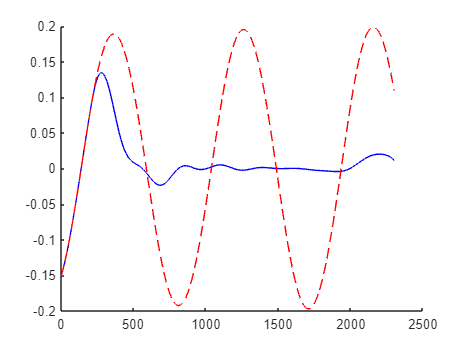



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
plot(prenewtraj.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(autoembed{2}(2,:),'--r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj.us,2)/stepps,size(prenewtraj.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


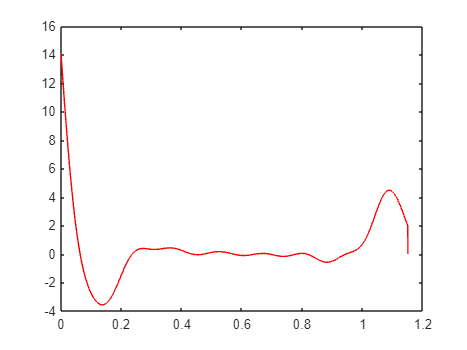

plot(figx,prenewtraj.us(1,:),'r','DisplayName', 'lqr us')

%xlim([0,0.1])

realsystem1

utnew=[prenewtraj.us(1,:)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew,2)/stepps,size(utnew,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew,2)

prestep = 2300

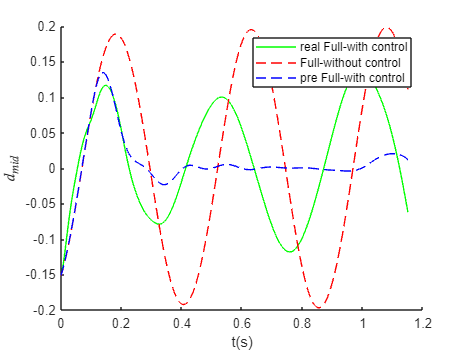

tpref=size(utnew,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-1;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength),'r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.02])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

%set(gca,'FontSize',18)


DMD2

urandtotalsp2=[utnew,urandtotalsp];

totaldatalength2=size(urandtotalsp2,2)

totaldatalength2 = 9758


if totaldatalength2>nsteps-ustart
    totaldatalength2=nsteps-ustart;
    urandtotalsp2=urandtotalsp2(:,1:totaldatalength2)
end

urandtotalsp2 =    14.0495   13.8985   13.7476   13.5969   13.4464   13.2961   13.1459   12.9961   12.8464   12.6971   12.5480   12.3992   12.2508   12.1027   11.9550   11.8076   11.6606   11.5140   11.3679   11.2222   11.0769   10.9322   10.7879   10.6441   10.5008   10.3581   10.2159   10.0742    9.9331    9.7927    9.6528    9.5135    9.3748    9.2368    9.0995    8.9628    8.8267    8.6914    8.5567    8.4228    8.2895    8.1570    8.0253    7.8943    7.7640    7.6345    7.5057    7.3778    7.2506    7.1243


nstepsp=totaldatalength2;
tfsp=(totaldatalength2)/stepps;
urandtime=linspace(0,tfsp,nstepsp);
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandtotalsp2',t));
set(DS,'u',ufun)
[tfullwRcsp2, xfullwRcsp2,~,xalldimsp2] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


%tcdim=100;
datalength2=totaldatalength2;
datastart=1;
%p=tcdim+2;
%r=1;
rembed=5;
windownum=1

windownum = 1

%auto1=yRec{2};
auto1=xfullwoT(:,ustart:end);
auto1=auto1(:,1:datalength2);
xrc1=xfullwRcsp2(:,1:4)*phiend;
xrc1=xrc1(1:datalength2,:)';
X=(xrc1-auto1)/epsilon;

urand1=urandtotalsp2%(1,SSMstart:SSMstart+datalength);

urand1 =    14.0495   13.8985   13.7476   13.5969   13.4464   13.2961   13.1459   12.9961   12.8464   12.6971   12.5480   12.3992   12.2508   12.1027   11.9550   11.8076   11.6606   11.5140   11.3679   11.2222   11.0769   10.9322   10.7879   10.6441   10.5008   10.3581   10.2159   10.0742    9.9331    9.7927    9.6528    9.5135    9.3748    9.2368    9.0995    8.9628    8.8267    8.6914    8.5567    8.4228    8.2895    8.1570    8.0253    7.8943    7.7640    7.6345    7.5057    7.3778    7.2506    7.1243


nstepdmd=datalength2;%总数据长度
tfdmd=(datalength2)/stepps;
tspandmd=linspace(0,tfdmd,nstepdmd);


%%%%%%%%%%delay embed

DMDdim=100

DMDdim = 100


Xcell=cell(1,2);
ucell=cell(1,2);

Xcell{1}=tspandmd;
Xcell{2}=X(:,1:end);
ucell{1}=tspandmd;
ucell{2}=urand1;

overEmbed = 0;
Xembed = coordinatesEmbedding(Xcell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.


uembed = coordinatesEmbedding(ucell, 1, 'OverEmbedding', overEmbed);

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


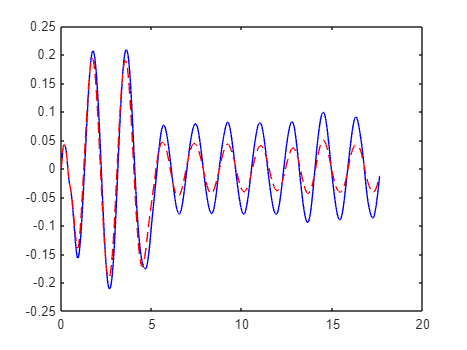

datalengthemb=size(Xembed{2},2)-1;
rembed=size(Xembed{2},1);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength-1,datastart,r,windownum,X,urand1);
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,rembed,windownum,Xembed{2},uembed{2});
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength,datastart,rembed,windownum,X,urand1);
[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,30,windownum,Xembed{2},urand1,0);

feedback test 1

feedbackpoint1=400;
utnewhalf=[prenewtraj.us(1,1:feedbackpoint1),zeros(1,LQRlength-feedbackpoint1)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnewhalf,2)/stepps,size(utnewhalf,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnewhalf,2)

prestep = 2500

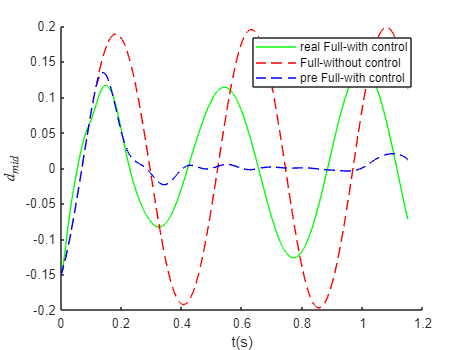

tpref=size(utnewhalf,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnewhalf',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,alldimfbpoint1,xalldimreal] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(prenewtraj.xt,2)-1;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength)','r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

%set(gca,'FontSize',18)

xbehindtemp=xalldimreal(1:figlength,1:4)*phiend;
xbehind=xbehindtemp(feedbackpoint1:end,useddim)';
%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell=cell(1,2)

xbehindcell = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbehindcell{1}=tspanLQR(:,1:size(xbehind,2));
%xbehindcell{2}=xbehind;
xbehindcell{2}=xbehind;
xbehindembed = coordinatesEmbedding(xbehindcell, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


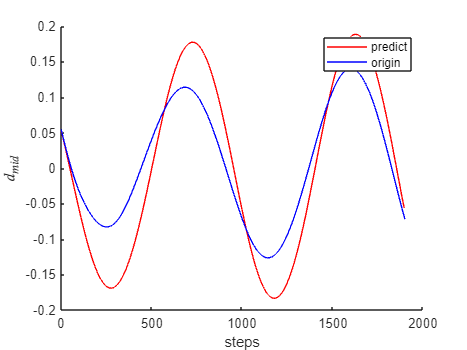

 [xbhRec, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed);
 figure();
 hold on;
 plot(xbhRec{2}(2,:),'r','DisplayName', 'predict');
 plot(xbehind(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')

LQR2

LQRlength2=size(xbhRec{2},2);

tspan2=linspace(datastart,datastart+LQRlength2-1,LQRlength2);
%autodata2=xbehind;
autodata2=xbhRec{2}(1,:);

autocell2=cell(1,2);

tspanLQR2=linspace(0,LQRlength2/stepps,LQRlength2)

tspanLQR2 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell2{1}=tspanLQR2(:,1:LQRlength2);
autocell2{2}=autodata2(:,1:LQRlength2);

autoembed2 = coordinatesEmbedding(autocell2, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



xbhcell=cell(1,2)

xbhcell = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbhcell{1}=tspanLQR2(:,1:LQRlength2);
xbhcell{2}=xbehind(:,1:LQRlength2);
xbhembeded = coordinatesEmbedding(xbhcell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



%targetdata2=autoembed2{2};
targetdata2=xbhembeded{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed2{2},2);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,5,windownum,Xembed{2},urand1,0);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj2 = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed2{2},targetdata2,windownum,epsil,DS,1,80)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2602    0.2702    0.2802    0.2902    0.3002    0.3102    0.3202    0.3302    0.3402    0.3502    0.3602    0.3702    0.3802    0.3902    0.4002    0.4102    0.4202    0.4303    0.4403    0.4503    0.4603    0.4703    0.4803    0.4903


prenewtraj2 = 包含以下字段的 struct :
     time: [1 2.0004 3.0008 4.0012 5.0016 6.0020 7.0024 8.0028 9.0032 10.0036 11.0040 12.0044 13.0048 14.0052 15.0056 16.0060 17.0064 18.0068 19.0072 20.0076 21.0080 22.0084 23.0088 24.0092 25.0096 26.0100 27.0104 28.0108 29.0112 30.0116 31.0120 … ]
       us: [-5.8289 -5.7062 -5.5842 -5.4629 -5.3424 -5.2227 -5.1037 -4.9854 -4.8679 -4.7512 -4.6353 -4.5202 -4.4059 -4.2923 -4.1796 -4.0676 -3.9565 -3.8462 -3.7367 -3.6281 -3.5202 -3.4132 -3.3070 -3.2017 -3.0972 -2.9936 -2.8908 -2.7889 -2.6878 … ]
       xt: [201×1696 double]
    xauto: [201×1696 double]


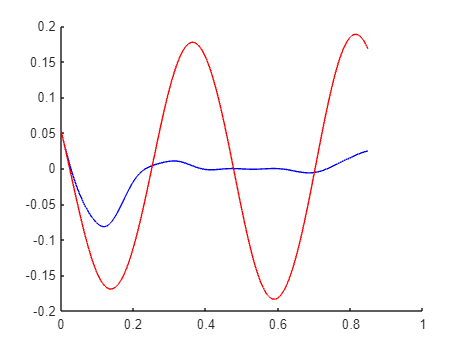



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj2.xt,2)/stepps,size(prenewtraj2.xt,2));
plot(figx,prenewtraj2.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed2{2}(2,:),'r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj2.us,2)/stepps,size(prenewtraj2.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


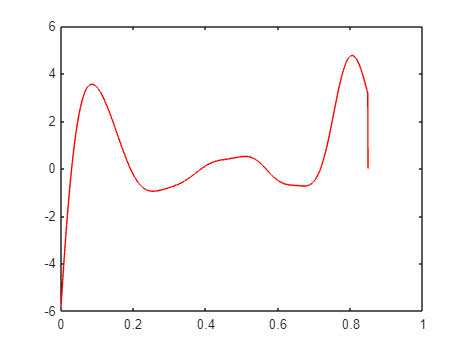

plot(figx,prenewtraj2.us(1,:),'r','DisplayName', 'lqr us')

feedback real system1

utnew2=[prenewtraj.us(:,1:feedbackpoint1),prenewtraj2.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew2,2)/stepps,size(utnew2,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew2,2);
tpref=size(utnew2,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

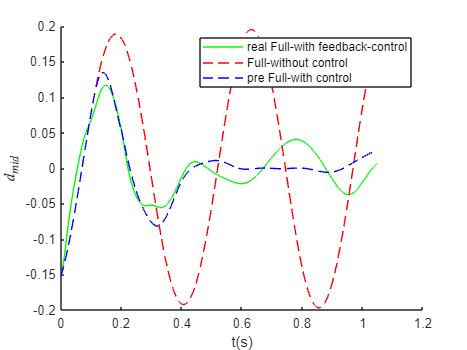


figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength),'r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

feedback test 2

feedbackpoint2=1000;
utnewhalf2=[utnew2(1,1:feedbackpoint2),zeros(1,LQRlength-feedbackpoint2)];
%utnew=[zeros(1,3000),100*ones(1,10000)]

tpref2=size(utnewhalf2,2)/stepps;
closedtime2=linspace(0,tpref2,size(utnewhalf2,2))

closedtime2 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep2=size(utnewhalf2,2)

prestep2 = 2500

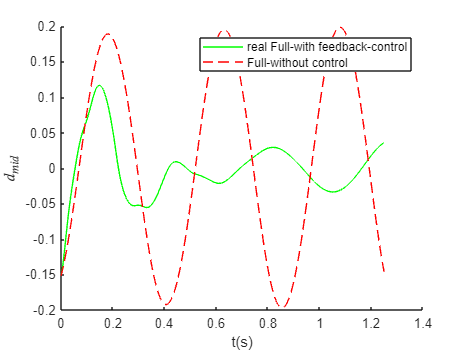


om = 2*pi/tpref2;
ufun = @(t) transpose(interp1(closedtime2,utnewhalf2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre2, xfullpre2,~,xalldimreal2] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep2,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimreal2,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal2(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
%plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

xbehind2=xalldimreal2(feedbackpoint2+1:end-1,1:4)*phiend;
xbehind2=xbehind2'

xbehind2 =    -0.0049   -0.0051   -0.0052   -0.0054   -0.0055   -0.0056   -0.0057   -0.0059   -0.0060   -0.0061   -0.0062   -0.0063   -0.0064   -0.0065   -0.0066   -0.0067   -0.0068   -0.0069   -0.0070   -0.0071   -0.0071   -0.0072   -0.0073   -0.0074   -0.0075   -0.0075   -0.0076   -0.0077   -0.0077   -0.0078   -0.0079   -0.0079   -0.0080   -0.0080   -0.0081   -0.0082   -0.0082   -0.0083   -0.0083   -0.0084   -0.0085   -0.0085   -0.0086   -0.0086   -0.0087   -0.0087   -0.0088   -0.0089   -0.0089   -0.0090


%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell2=cell(1,2)

xbehindcell2 = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbehindcell2{1}=tspanLQR(:,1:size(xbehind2,2));
xbehindcell2{2}=xbehind2;
xbehindembed2 = coordinatesEmbedding(xbehindcell2, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


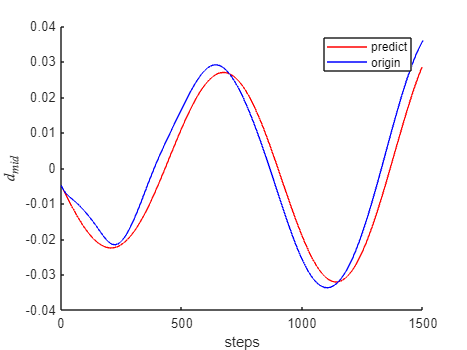


 [xbhRec2, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed2);
 figure();
 hold on;
 plot(xbhRec2{2}(1,:),'r','DisplayName', 'predict');
 plot(xbehind2(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')

LQR3

LQRlength3=LQRlength-feedbackpoint2-2*DMDdim;

tspan3=linspace(datastart,datastart+LQRlength3-1,LQRlength3);
%autodata2=xbehind;
autodata3=xbhRec2{2}(1,:);

autocell3=cell(1,2);

tspanLQR3=linspace(0,LQRlength3/stepps,LQRlength3)

tspanLQR3 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell3{1}=tspanLQR3(:,1:LQRlength3);
autocell3{2}=autodata3(:,1:LQRlength3);
autoembed3 = coordinatesEmbedding(autocell3, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



xbhcell2=cell(1,2)

xbhcell2 = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbhcell2{1}=tspanLQR2(:,1:LQRlength3);
xbhcell2{2}=xbehind2(:,1:LQRlength3);
xbhembeded2 = coordinatesEmbedding(xbhcell2, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.




%targetdata2=autoembed2{2};
targetdata3=xbhembeded2{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed3{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj3 = LQRwdz3(tspan3,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed3{2},targetdata3,windownum,epsil,DS,1,40)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2502    0.2602    0.2702    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3503    0.3603    0.3703    0.3803    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4504    0.4604    0.4704    0.4804    0.4904


prenewtraj3 = 包含以下字段的 struct :
     time: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 … ]
       us: [-0.3872 -0.3717 -0.3562 -0.3409 -0.3258 -0.3107 -0.2957 -0.2809 -0.2662 -0.2516 -0.2371 -0.2228 -0.2085 -0.1944 -0.1804 -0.1665 -0.1528 -0.1391 -0.1256 -0.1122 -0.0990 -0.0858 -0.0728 -0.0599 -0.0471 -0.0344 -0.0219 -0.0095 0.0028 0.0150 … ]
       xt: [201×1100 double]
    xauto: [201×1100 double]


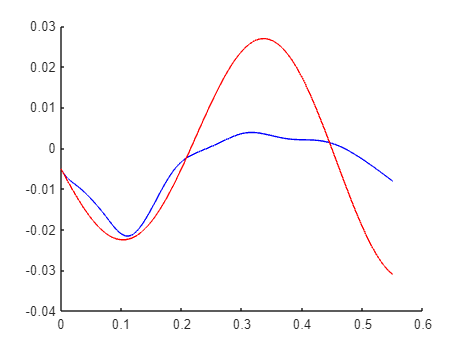



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj3.xt,2)/stepps,size(prenewtraj3.xt,2));
plot(figx,prenewtraj3.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed3{2}(2,:),'r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj3.us,2)/stepps,size(prenewtraj3.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


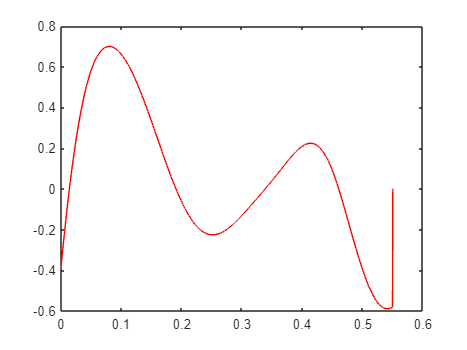

plot(figx,prenewtraj3.us(1,:),'r','DisplayName', 'lqr us')

feedback real system2

utnew3=[utnew2(1,1:feedbackpoint2),prenewtraj3.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew3,2)/stepps,size(utnew3,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew3,2);
tpref=size(utnew3,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew3',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,~,xalldimpre3] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode45','outdof',outdof,'init',z0ssmstart);

%load canti_fs6_bestfor5.mat
figure;
hold on
feedbacktraj2=[prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:feedbackpoint2-feedbackpoint1),prenewtraj3.xt(1,1:end)];
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimpre3,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimpre3(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, feedbacktraj2(1:size(figx,2)),'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("$t$[s]",'Interpreter','latex')
ylabel("$y_{\rm{end}}$",'Interpreter','latex')
figure()
plot(figx, utnew3(:,1:end-1),'b','DisplayName', 'ut');


close all

LQRlength=2500;

tspan1=linspace(datastart,datastart+LQRlength,LQRlength);
autodata=xalldimwo(SSMstart+1:SSMstart+LQRlength,useddim)';
epsil=DS.epsilon;


%z00=autodata(:,1);
autocell=cell(1,2);

tspanLQR=linspace(0,LQRlength/stepps,LQRlength)

tspanLQR =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


autocell{1}=tspanLQR(:,1:LQRlength);
autocell{2}=autodata(:,1:LQRlength);

autoembed = coordinatesEmbedding(autocell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



% Ecell=cell(1,2)
% Ecell{1}=tspanLQR(:,1:LQRlength);
% xalldimwET=xalldimwE';
% Ecell{2}=xalldimwET(useddim,SSMstart+1:SSMstart+LQRlength);
% Eembed = coordinatesEmbedding(Ecell, DMDdim, 'OverEmbedding', overEmbed);

targetdata=autoembed{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed{2},targetdata,windownum,epsil,DS,1,45)

closedtime =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3001    0.3101    0.3201    0.3301    0.3401    0.3502    0.3602    0.3702    0.3802    0.3902    0.4002    0.4102    0.4202    0.4302    0.4402    0.4502    0.4602    0.4702    0.4802    0.4902


prenewtraj = 包含以下字段的 struct :
     time: [1 2.0004 3.0008 4.0012 5.0016 6.0020 7.0024 8.0028 9.0032 10.0036 11.0040 12.0044 13.0048 14.0052 15.0056 16.0060 17.0064 18.0068 19.0072 20.0076 21.0080 22.0084 23.0088 24.0092 25.0096 26.0100 27.0104 28.0108 29.0112 30.0116 31.0120 … ]
       us: [14.1950 14.0438 13.8927 13.7418 13.5910 13.4403 13.2899 13.1396 12.9896 12.8397 12.6901 12.5408 12.3917 12.2429 12.0943 11.9461 11.7981 11.6505 11.5032 11.3562 11.2096 11.0634 10.9175 10.7720 10.6269 10.4822 10.3380 10.1941 10.0507 9.9078 … ]
       xt: [201×2300 double]
    xauto: [201×2300 double]


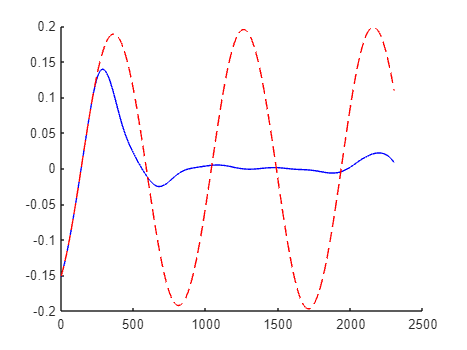



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
plot(prenewtraj.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(autoembed{2}(2,:),'--r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj.us,2)/stepps,size(prenewtraj.us,2))

figx =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


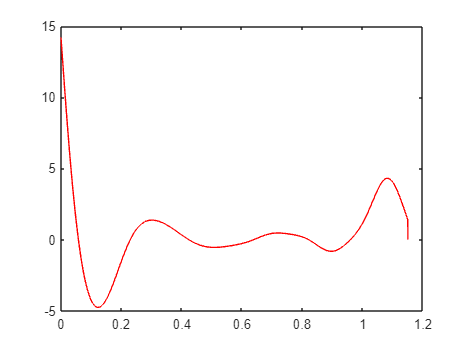

plot(figx,prenewtraj.us(1,:),'r','DisplayName', 'lqr us')

%xlim([0,0.1])

realsystem1

utnew=[prenewtraj.us(1,:)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew,2)/stepps,size(utnew,2))

closedtime =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


%closedtime=0:h:0.65-h;
prestep=size(utnew,2)

prestep = 2300

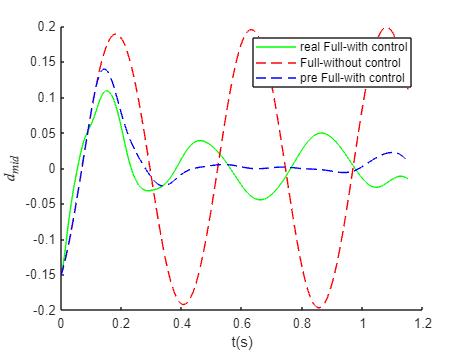

tpref=size(utnew,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-1;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength),'r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.02])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

%set(gca,'FontSize',18)


DMD2

urandtotalsp2=[utnew,urandtotalsp];

totaldatalength2=size(urandtotalsp2,2)

totaldatalength2 = 9758


if totaldatalength2>nsteps-ustart
    totaldatalength2=nsteps-ustart;
    urandtotalsp2=urandtotalsp2(:,1:totaldatalength2)
end

urandtotalsp2 = 1×9000
   14.1950   14.0438   13.8927   13.7418   13.5910   13.4403   13.2899   13.1396   12.9896   12.8397   12.6901   12.5408   12.3917   12.2429   12.0943   11.9461   11.7981   11.6505   11.5032   11.3562   11.2096   11.0634   10.9175   10.7720   10.6269   10.4822   10.3380   10.1941   10.0507    9.9078


nstepsp=totaldatalength2;
tfsp=(totaldatalength2)/stepps;
urandtime=linspace(0,tfsp,nstepsp);
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandtotalsp2',t));
set(DS,'u',ufun)
[tfullwRcsp2, xfullwRcsp2,~,xalldimsp2] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


%tcdim=100;
datalength2=totaldatalength2;
datastart=1;
%p=tcdim+2;
%r=1;
rembed=5;
windownum=1

windownum = 1

%auto1=yRec{2};
auto1=xfullwoT(:,ustart:end);
auto1=auto1(:,1:datalength2);
xrc1=xfullwRcsp2(:,1:4)*phiend;
xrc1=xrc1(1:datalength2,:)';
X=(xrc1-auto1)/epsilon;

urand1=urandtotalsp2%(1,SSMstart:SSMstart+datalength);

urand1 = 1×9000
   14.1950   14.0438   13.8927   13.7418   13.5910   13.4403   13.2899   13.1396   12.9896   12.8397   12.6901   12.5408   12.3917   12.2429   12.0943   11.9461   11.7981   11.6505   11.5032   11.3562   11.2096   11.0634   10.9175   10.7720   10.6269   10.4822   10.3380   10.1941   10.0507    9.9078


nstepdmd=datalength2;%总数据长度
tfdmd=(datalength2)/stepps;
tspandmd=linspace(0,tfdmd,nstepdmd);


%%%%%%%%%%delay embed

DMDdim=100

DMDdim = 100


Xcell=cell(1,2);
ucell=cell(1,2);

Xcell{1}=tspandmd;
Xcell{2}=X(:,1:end);
ucell{1}=tspandmd;
ucell{2}=urand1;

overEmbed = 0;
Xembed = coordinatesEmbedding(Xcell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.


uembed = coordinatesEmbedding(ucell, 1, 'OverEmbedding', overEmbed);

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


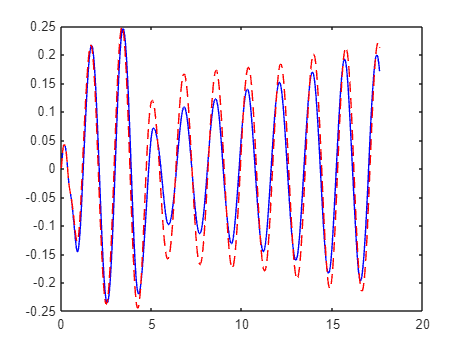

datalengthemb=size(Xembed{2},2)-1;
rembed=size(Xembed{2},1);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength-1,datastart,r,windownum,X,urand1);
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,rembed,windownum,Xembed{2},uembed{2});
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength,datastart,rembed,windownum,X,urand1);
[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,30,windownum,Xembed{2},urand1,0);

feedback test 1

feedbackpoint1=400;
utnewhalf=[prenewtraj.us(1,1:feedbackpoint1),zeros(1,LQRlength-feedbackpoint1)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnewhalf,2)/stepps,size(utnewhalf,2))

closedtime = 1×2500
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


%closedtime=0:h:0.65-h;
prestep=size(utnewhalf,2)

prestep = 2500

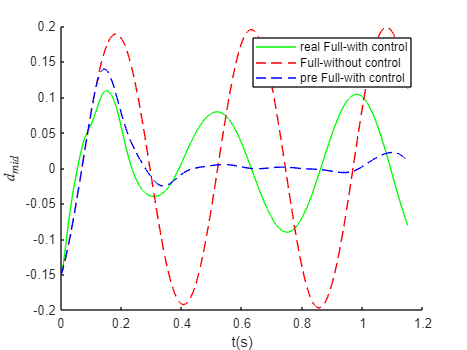

tpref=size(utnewhalf,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnewhalf',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,alldimfbpoint1,xalldimreal] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(prenewtraj.xt,2)-1;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength)','r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

%set(gca,'FontSize',18)

xbehindtemp=xalldimreal(1:figlength,1:4)*phiend;
xbehind=xbehindtemp(feedbackpoint1:end,useddim)';
%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell=cell(1,2)

xbehindcell = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbehindcell{1}=tspanLQR(:,1:size(xbehind,2));
%xbehindcell{2}=xbehind;
xbehindcell{2}=xbehind;
xbehindembed = coordinatesEmbedding(xbehindcell, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


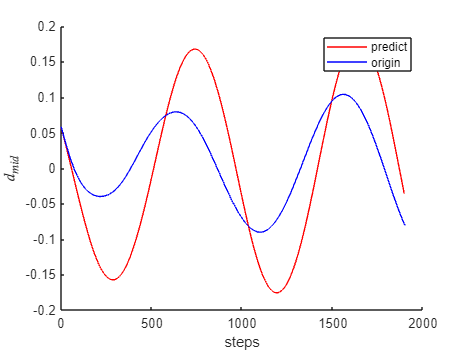

 [xbhRec, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed);
 figure();
 hold on;
 plot(xbhRec{2}(2,:),'r','DisplayName', 'predict');
 plot(xbehind(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')

LQR2

LQRlength2=size(xbhRec{2},2);

tspan2=linspace(datastart,datastart+LQRlength2-1,LQRlength2);
%autodata2=xbehind;
autodata2=xbhRec{2}(1,:);

autocell2=cell(1,2);

tspanLQR2=linspace(0,LQRlength2/stepps,LQRlength2)

tspanLQR2 = 1×1896
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


autocell2{1}=tspanLQR2(:,1:LQRlength2);
autocell2{2}=autodata2(:,1:LQRlength2);

autoembed2 = coordinatesEmbedding(autocell2, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



xbhcell=cell(1,2)

xbhcell = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbhcell{1}=tspanLQR2(:,1:LQRlength2);
xbhcell{2}=xbehind(:,1:LQRlength2);
xbhembeded = coordinatesEmbedding(xbhcell, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



%targetdata2=autoembed2{2};
targetdata2=xbhembeded{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed2{2},2);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,5,windownum,Xembed{2},urand1,0);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj2 = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed2{2},targetdata2,windownum,epsil,DS,1,80)

closedtime = 1×1696
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2602    0.2702    0.2802    0.2902


prenewtraj2 = 包含以下字段的 struct :
     time: [1 2.0004 3.0008 4.0012 5.0016 6.0020 7.0024 8.0028 9.0032 10.0036 11.0040 12.0044 13.0048 14.0052 15.0056 16.0060 17.0064 18.0068 19.0072 20.0076 21.0080 22.0084 23.0088 24.0092 25.0096 26.0100 27.0104 28.0108 29.0112 30.0116 31.0120 … ]
       us: [-1.7155 -1.6595 -1.6040 -1.5489 -1.4941 -1.4398 -1.3859 -1.3324 -1.2794 -1.2267 -1.1745 -1.1227 -1.0714 -1.0204 -0.9699 -0.9198 -0.8702 -0.8210 -0.7722 -0.7238 -0.6759 -0.6284 -0.5814 -0.5348 -0.4886 -0.4429 -0.3976 -0.3528 -0.3084 … ]
       xt: [201×1696 double]
    xauto: [201×1696 double]


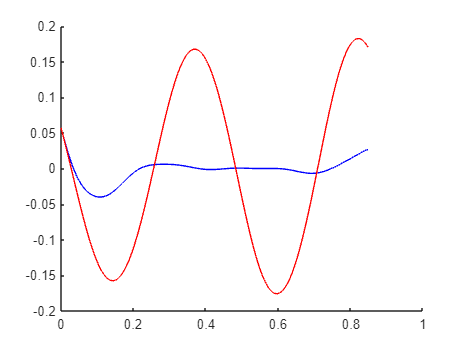



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj2.xt,2)/stepps,size(prenewtraj2.xt,2));
plot(figx,prenewtraj2.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed2{2}(2,:),'r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj2.us,2)/stepps,size(prenewtraj2.us,2))

figx = 1×1696
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


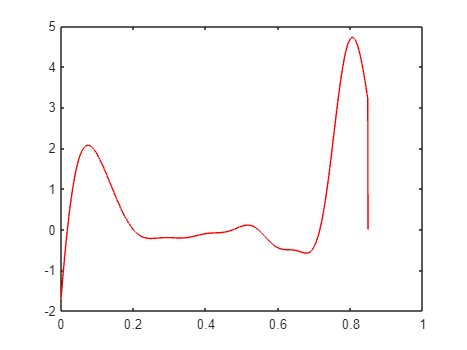

plot(figx,prenewtraj2.us(1,:),'r','DisplayName', 'lqr us')

feedback real system1

utnew2=[prenewtraj.us(:,1:feedbackpoint1),prenewtraj2.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew2,2)/stepps,size(utnew2,2))

closedtime = 1×2096
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


%closedtime=0:h:0.65-h;
prestep=size(utnew2,2);
tpref=size(utnew2,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

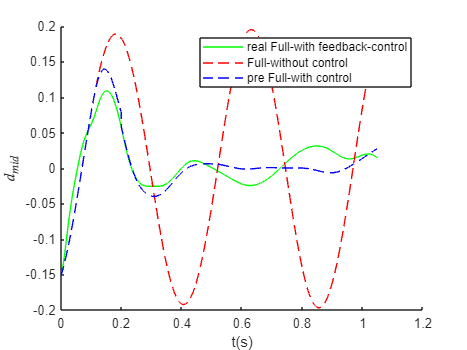


figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xfullwoT(1,SSMstart+1:SSMstart+figlength),'r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

feedback test 2

feedbackpoint2=1000;
utnewhalf2=[utnew2(1,1:feedbackpoint2),zeros(1,LQRlength-feedbackpoint2)];
%utnew=[zeros(1,3000),100*ones(1,10000)]

tpref2=size(utnewhalf2,2)/stepps;
closedtime2=linspace(0,tpref2,size(utnewhalf2,2))

closedtime2 = 1×2500
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


%closedtime=0:h:0.65-h;
prestep2=size(utnewhalf2,2)

prestep2 = 2500

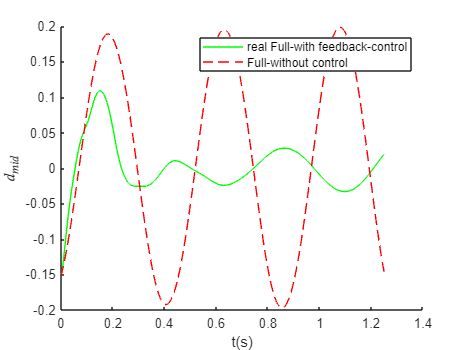


om = 2*pi/tpref2;
ufun = @(t) transpose(interp1(closedtime2,utnewhalf2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre2, xfullpre2,~,xalldimreal2] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep2,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimreal2,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal2(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
%plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')

xbehind2=xalldimreal2(feedbackpoint2+1:end-1,1:4)*phiend;
xbehind2=xbehind2'

xbehind2 = 1×1500
    0.0002    0.0001   -0.0000   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0026   -0.0027   -0.0028   -0.0029


%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell2=cell(1,2)

xbehindcell2 = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbehindcell2{1}=tspanLQR(:,1:size(xbehind2,2));
xbehindcell2{2}=xbehind2;
xbehindembed2 = coordinatesEmbedding(xbehindcell2, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


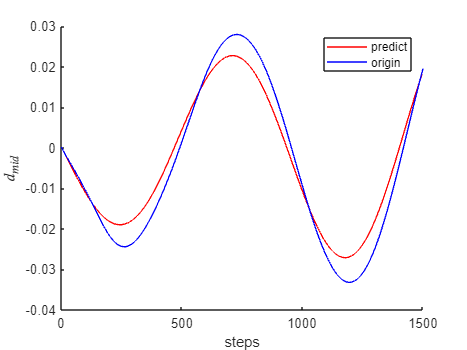


 [xbhRec2, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed2);
 figure();
 hold on;
 plot(xbhRec2{2}(1,:),'r','DisplayName', 'predict');
 plot(xbehind2(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')

LQR3

LQRlength3=LQRlength-feedbackpoint2-2*DMDdim;

tspan3=linspace(datastart,datastart+LQRlength3-1,LQRlength3);
%autodata2=xbehind;
autodata3=xbhRec2{2}(1,:);

autocell3=cell(1,2);

tspanLQR3=linspace(0,LQRlength3/stepps,LQRlength3)

tspanLQR3 = 1×1300
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


autocell3{1}=tspanLQR3(:,1:LQRlength3);
autocell3{2}=autodata3(:,1:LQRlength3);
autoembed3 = coordinatesEmbedding(autocell3, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.



xbhcell2=cell(1,2)

xbhcell2 = 1×2 cell 数组
    {0×0 double}    {0×0 double}


xbhcell2{1}=tspanLQR2(:,1:LQRlength3);
xbhcell2{2}=xbehind2(:,1:LQRlength3);
xbhembeded2 = coordinatesEmbedding(xbhcell2, DMDdim, 'OverEmbedding', overEmbed);

The 201 embedding coordinates consist of the measured state and its 200 time-delayed measurements.




%targetdata2=autoembed2{2};
targetdata3=xbhembeded2{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed3{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj3 = LQRwdz3(tspan3,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed3{2},targetdata3,windownum,epsil,DS,1,40)

closedtime = 1×1100
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2502    0.2602    0.2702    0.2803    0.2903


prenewtraj3 = 包含以下字段的 struct :
     time: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 … ]
       us: [-1.2691 -1.2479 -1.2268 -1.2057 -1.1848 -1.1640 -1.1432 -1.1225 -1.1020 -1.0815 -1.0611 -1.0409 -1.0207 -1.0006 -0.9807 -0.9608 -0.9410 -0.9214 -0.9018 -0.8824 -0.8630 -0.8438 -0.8247 -0.8057 -0.7868 -0.7680 -0.7493 -0.7307 -0.7123 … ]
       xt: [201×1100 double]
    xauto: [201×1100 double]


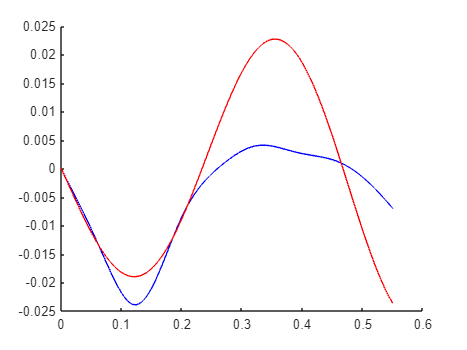



figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj3.xt,2)/stepps,size(prenewtraj3.xt,2));
plot(figx,prenewtraj3.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed3{2}(2,:),'r','DisplayName', 'Full-without control')

%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj3.us,2)/stepps,size(prenewtraj3.us,2))

figx = 1×1100
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


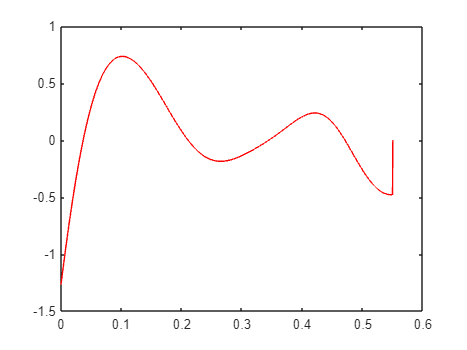

plot(figx,prenewtraj3.us(1,:),'r','DisplayName', 'lqr us')

feedback real system2

utnew3=[utnew2(1,1:feedbackpoint2),prenewtraj3.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew3,2)/stepps,size(utnew3,2))

closedtime = 1×2100
         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145


%closedtime=0:h:0.65-h;
prestep=size(utnew3,2);
tpref=size(utnew3,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew3',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,~,xalldimpre3] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode45','outdof',outdof,'init',z0ssmstart);

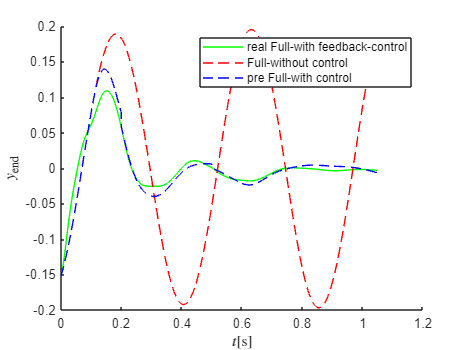


figure;
hold on
feedbacktraj2=[prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:feedbackpoint2-feedbackpoint1),prenewtraj3.xt(1,1:end)];
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimpre3,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimpre3(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, feedbacktraj2(1:size(figx,2)),'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("$t$[s]",'Interpreter','latex')
ylabel("$y_{\rm{end}}$",'Interpreter','latex')

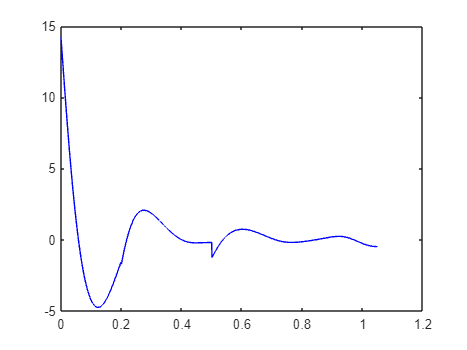

figure()
plot(figx, utnew3(:,1:end-1),'b','DisplayName', 'ut');